# `※ Assignment #1`

#### ***2021-21674 권준우***

# **■ Assignment #1-(1)**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Assignment #1-(1)
%%% by Joonwoo Kwon (pioneers@snu.ac.kr)
%%% Due : 2021. 04. 16.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate and plot the two-dimensional intensity distribution
% of the diffraction patterns in the x-z plane
% using the first Rayleigh-Sommerfeld diffration integral
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all;
clear;
clc;

## parameters

% light
lambda = 0.0005; % mm, wavelength: 500nm
k = 2*pi/lambda; % vacuum wavenumber
a= 1.0; % mm, aperture size

% observation plane
Nx = 1024; % sampling points
Nz = 1024; % sampling points

x_RS = linspace(-1,1,Nx); % observation coordinate - x (mm, half-width of the observation screen)
z_RS = linspace(1,700,Nz); % observation coordinate - z


## First Rayleigh-Sommerfeld diffraction integral


values_RS = zeros(Nx, Nz); % set a zero nullspace in xz-plane.

for cnt = (1:length(z_RS))
    func_RS = @(x_poi) exp(1i*k.*sqrt((x_RS-x_poi).^2+z_RS(cnt).^2))./sqrt((x_RS-x_poi).^2+z_RS(cnt).^2).*...
                   (z_RS(cnt)./sqrt((x_RS-x_poi).^2+z_RS(cnt).^2));
    E_RS = -1i/lambda*integral(func_RS, -a/2, a/2, 'ArrayValued', true);
    % Normalize 
    Abs_RS = abs(E_RS).^2; % I=I(x)/max(I(x))
    values_RS(:,cnt) = Abs_RS./max(Abs_RS);
end


## Plot

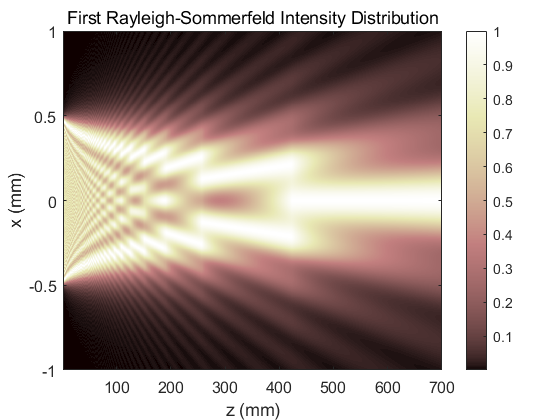

figure;imagesc(z_RS,x_RS,values_RS);colormap('pink');colorbar;
title('First Rayleigh-Sommerfeld Intensity Distribution')
set(gca,'FontSize',12);
set(gca,'YDir','normal'); % set y-direction
xlabel('z (mm)');
ylabel('x (mm)');

# **■ Assignment #1-(2)**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate and plot the two-dimensional intensity distribution
% of the diffraction patterns in the x-z plane
% using Fresnel approximation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## parameters


% light
lambda = 0.0005; % mm, wavelength: 500nm
k = 2*pi/lambda; % vacuum wavenumber
a= 1.0; % mm, aperture size

% observation plane
Nx = 1024; % sampling points
Nz = 1024; % sampling points

x_FN = linspace(-1,1,Nx); % observation coordinate - x (mm, half-width of the observation screen)
z_FN = linspace(1,700,Nz); % observation coordinate - z
values_FN = zeros(Nx, Nz); % set a zero nullspace in xz-plane.


## Fresnel approximation


for cnt = (1:length(z_FN))
    func_FN = @(x_poi) exp((1i*k./(2*z_FN(cnt))).*((x_FN-x_poi).^2));
    E_FN = -1i*exp(1i*k*z_FN(cnt))/(lambda*z_FN(cnt))...
        *integral(func_FN,-a/2,a/2,'ArrayValued',true);
    % Normalize 
    Abs_FN = abs(E_FN).^2; % I=I(x)/max(I(x))
    values_FN(:,cnt) = Abs_FN./max(Abs_FN);
end


## Plot 1 : Intensity Distribution

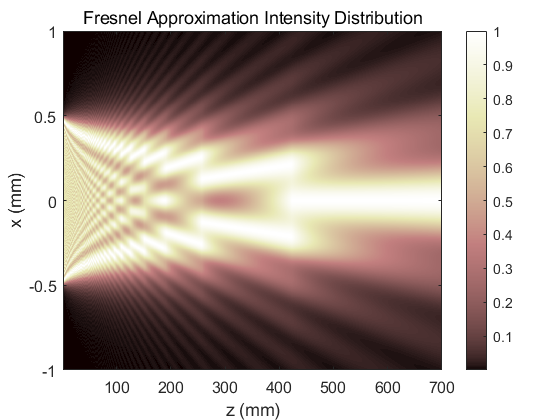


figure;imagesc(z_FN,x_FN,values_FN);colormap('pink');colorbar;
title('Fresnel Approximation Intensity Distribution')
set(gca,'FontSize',12);
set(gca,'YDir','normal'); % set y-direction
xlabel('z (mm)');
ylabel('x (mm)');

## Plot 2 : Subtracted result between Rayleigh-Sommerfeld and Fresnel

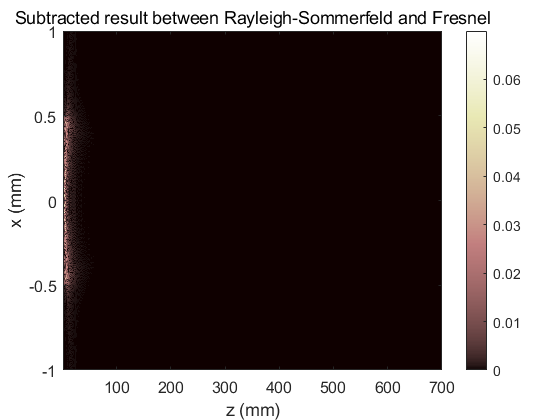

diff_RSFN = abs(values_RS-values_FN);
figure; imagesc(z_FN,x_FN,diff_RSFN);colormap('pink');colorbar;
title('Subtracted result between Rayleigh-Sommerfeld and Fresnel')
set(gca,'FontSize',12);
set(gca,'YDir','normal'); % set y-direction
xlabel('z (mm)');
ylabel('x (mm)');


% As you can see, most differences are in between 1-50mm z-range

## Plot 3 : Subtracted result between Rayleigh-Sommerfeld and Fresnel

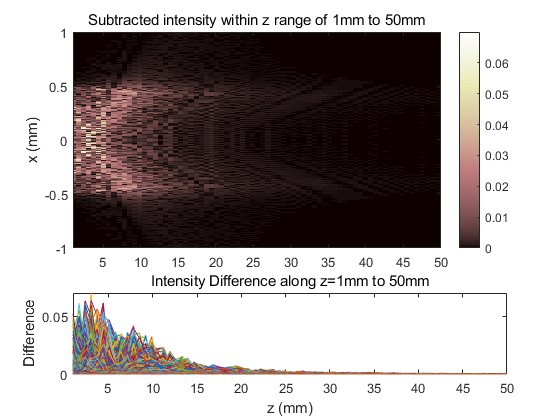

figure; subplot(3,1,[1,2]); imagesc(z_FN,x_FN,diff_RSFN);colormap('pink');colorbar;
xlim([1,50]); % set 0-50mm z-range
set(gca,'FontSize',10);
set(gca,'YDir','normal');
title('Subtracted intensity within z range of 1mm to 50mm');
ylabel('x (mm)');

diff = transpose(diff_RSFN);
subplot(3,1,3); plot(z_FN,diff);
xlim([1,50]); % set 0-50mm z-range
set(gca,'FontSize',10);
title('Intensity Difference along z=1mm to 50mm');
xlabel('z (mm)');
ylabel('Difference');

오른쪽 그림과 같이 deviation은 z range가 0-50mm 사이에서 가장 크게 나타났다.

또한 50mm 이상의 area에선 두 방법간 intensity의 차이가 크지 않은 것을 확인할 수 있다.

따라서 Diffraction이 나타나는 z=0~50mm 간의 공간의 fresnel number를 아래와 같이 z 값에 따라 쭉 plot 해보도록 하겠다.

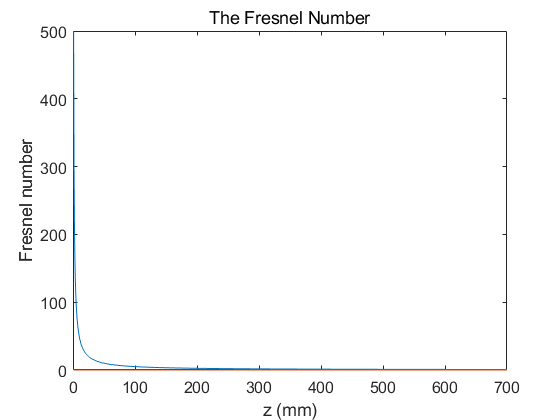

Fn_num = zeros(Nz);

for cnt = 1:length(z_FN)
    Fn_num(cnt) = ((a/2).^2)./(z_FN(cnt).*lambda);
end

figure; plot(z_FN, Fn_num);
set(gca, 'Fontsize', 12);
title('The Fresnel Number');
xlabel('z (mm)'); ylabel('Fresnel number');

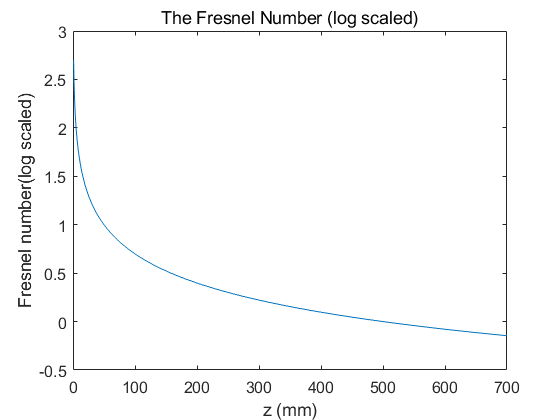


figure; plot(z_FN, log10(Fn_num));
set(gca, 'Fontsize', 12);
title('The Fresnel Number (log scaled)');
xlabel('z (mm)'); ylabel('Fresnel number(log scaled)');


L = 50;
Fresnel_number = ((a/2).^2)./(L.*lambda)

Fresnel_number = 10

Log scaled된 그래프로 확인했을때 z=50의 area에선 Fresnel number를 10으로 가지는 것을 확인할 수 있다.

또한 Far field diffraction은 Fresnel number가 1보다 작아지는 공간으로 정의하므로, 그래프를 통해 분석하면 약 z=500mm 근처 부터는 far field diffraction 된다고 할 수 있다.

# **■ Assignment #1-(3)**

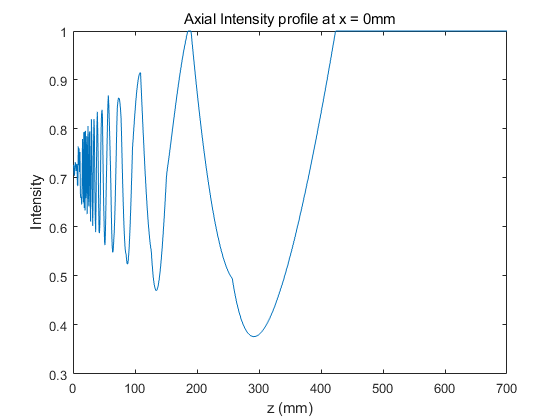

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot the axial intensity profile I(0,z) from the result 
% of assignment #1-(1)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure; plot(z_RS, values_RS((Nx/2),:))
set(gca,'FontSize',10);
title('Axial Intensity profile at x = 0mm');
xlabel('z (mm)');
ylabel('Intensity');

I(0,z), 즉 axial intensity profile를 plot 하면 위와 같다. 

이 결과를 보면 Intensity가 near-filed regime에서 fluctuate 하며 멀어질 수록 일정한 값으로 수렴하는 것을 볼 수 있다.

이는 경로차에 의한 간섭으로 인해 생기는 현상인데, Plane wave가 slit을 통과한 후 만들어지는 wave는 slit aperature

사이의 각 point에서 만들어지는 wave 라고 볼 수 있다. 즉, aperature 사이의 모든 점들을 wave를 발생하게 한 point source라고 간주하는 것이다.

이 때, 위상차는 point source로 부터 떨어진 거리에 의해 정의되므로 slit aperature와 가까운 거리에서는 그만큼 간섭이 많이 생겨 

intensity가 fluctuation하지만 aperature에서 멀어질 수록 간섭이 줄어들어 결국 slit aperature의 point source들이 

하나의 point source로 보이는 먼 거리에 오게 되면 일정한 intensity를 유지하게 된다.

========================================================================================================================

========================================================================================================================

========================================================================================================================

# **■ Assignment #2-(1)**

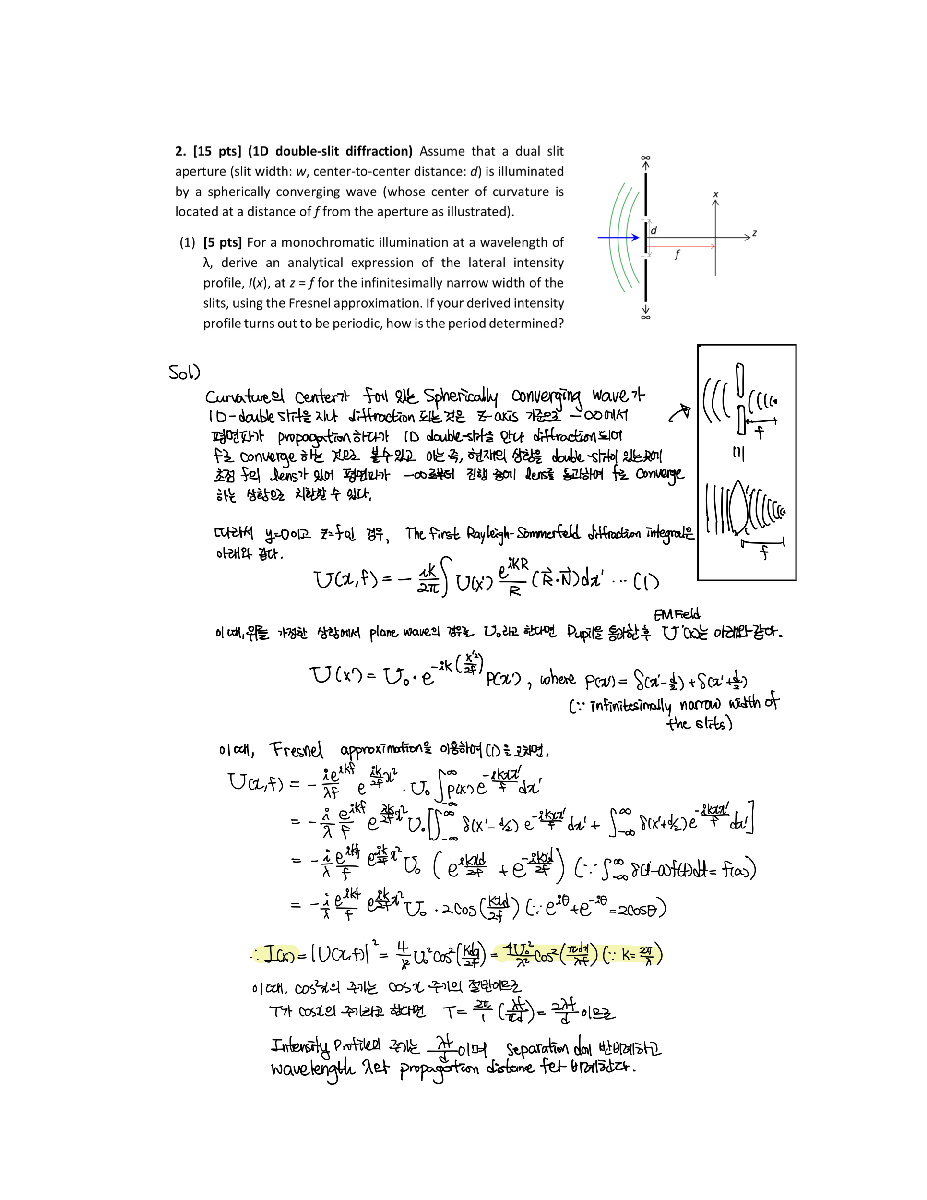

# **■ Assignment #2-(2)**

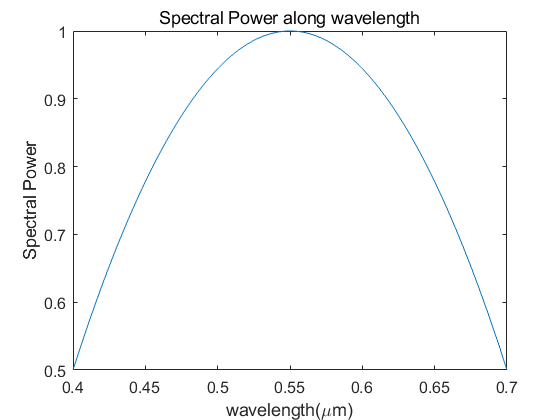

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot the lateral intensity profile over x=[-2.5mm, 2.5mm] if d=1mm,
% f=100mm.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
close all;
clear; clc;

d=1; % mm, slit width
f=100; % mm, distance
 
Nx = 5000; % Sampling points
Nz = 3000; % Sampling points
x= linspace(-2.5,2.5,Nx);
z= linspace(0.4,0.7,Nz); % lambda = [0.4mum, 0.7mum]
values = zeros(Nx,Nz);
values2 = zeros(Nx,Nz);
Power = zeros(Nz);

for cnt = 1:length(z)
    Power(cnt) = (1-22.222*((z(cnt)-0.55).^2));
    I = 4*(Power(cnt))*(cos((pi*d*x)./(f*(z(cnt)*0.001))).^2)./((z(cnt)*0.001).^2);
    values(:,cnt) = I/max(I); % normarlized.
end

figure; plot(z, Power);
set(gca, 'Fontsize', 12);
title('Spectral Power along wavelength');
xlabel('wavelength(\mum)'); ylabel('Spectral Power');
ylim([0.5,1]);

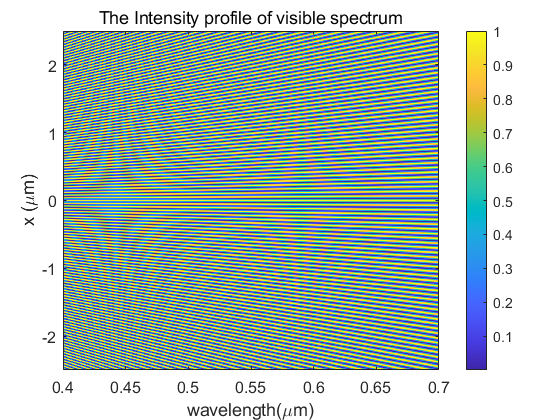

figure; imagesc(z,x,values); colorbar;
set(gca, 'Fontsize', 12);
set(gca, 'YDir', 'normal');
title('The Intensity profile of visible spectrum');
xlabel('wavelength(\mum)'); ylabel('x (\mum)');

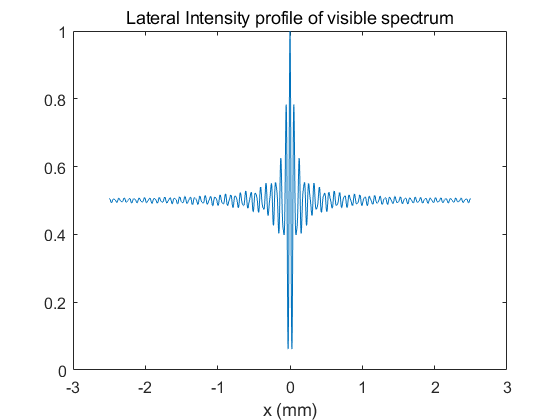


new_value = zeros(Nx,1);
temp = 0;
for i = 1:Nx
    new_value(i,:) = sum(values(i,:));
    temp = new_value./max(new_value);
end

figure; plot(x,temp);set(gca, 'Fontsize', 12);
xlabel('x (mm)'); title('Lateral Intensity profile of visible spectrum');

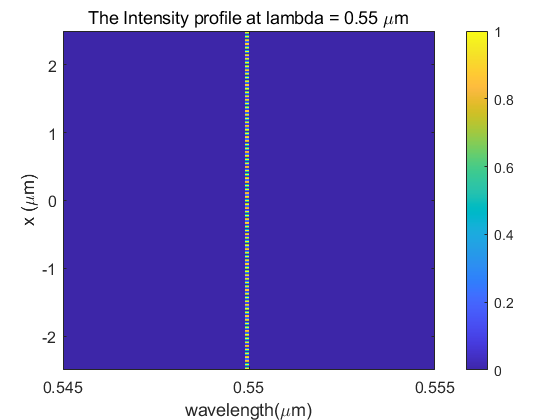

% Intensity profile at lambda = 0.55mum

Power_sp = (1-22.222*((0.55-0.55).^2));
I_mono = (4*Power_sp*(cos(pi*d*x./(f*(0.00055))).^2))./((0.00055).^2);
nor_I_mono = I_mono/max(I_mono);


for i = 1:length(z)
    v = 0.4+((0.0001)*i);
    if v == 0.55
        i;
        values2(:,i) = nor_I_mono;
        break
    end
end

figure; imagesc(z,x,values2); colorbar;
set(gca, 'Fontsize', 12);
xlim([0.545, 0.555])
set(gca, 'YDir', 'normal');
title('The Intensity profile at lambda = 0.55 \mum');
xlabel('wavelength(\mum)'); ylabel('x (\mum)');

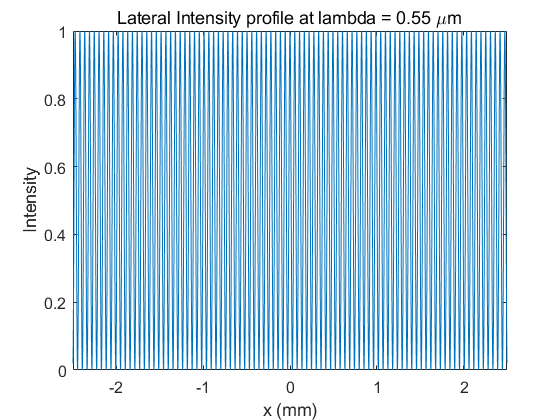

figure; plot(x,nor_I_mono); 
set(gca, 'Fontsize', 12);
xlim([-2.5 2.5]); title('Lateral Intensity profile at lambda = 0.55 \mum');
xlabel('x (mm)'); ylabel('Intensity');

Polychromatic illumination의 intensity profile과 Monochromatic illumination의 intensity profile은 크게 다르다. 

우선 Monochromatic illumination에 의한 intensity profile부터 보면 단일 파장으로 인해 간섭무늬가 생기게 되고, 이 간섭무늬가 Spectral Power와 곱해지는데 이 때, spectral power의 값이 1이므로 amplitude와 주기 모두 변하지 않은 단일 파장 간섭무늬를 만들게 된다.

하지만 Polychromatic illumination에 의한 intensity profile을 보면 0.4$\mu m$에서 0.7$\mu m$ 사이의 서로 다른 파장들로 인해 생긴 간섭무늬가 중첩되어 간섭 무늬가 생기게 된다. 또한 각 파장별로 곱해지는 spectral power의 값이 다르기 때문에 0.55$\mu m$ 근방에서는 1이 곱해지지만, 0.55$\mu m$에서 멀어질 수록 spectral power 값이 작아져 attenuation coefficient 같은 역할을 하게 된다. 또한 on-axis인 x=0 일 때, 파장들이 coherent하여 intensity가 최대가 되므로 그래프를 보면 x=0에서 최대 값을 가지며 x 값이 0에서 멀어질수록 intensity가 줄어드는 것을 알 수 있다.

이러한 이유로 Polychromatic illumination에 의한 intensity profile과 Monochromatic illumination에 의한 intensity profile은 다른 양상을 보인다.

# **■ Assignment #2-(3)**

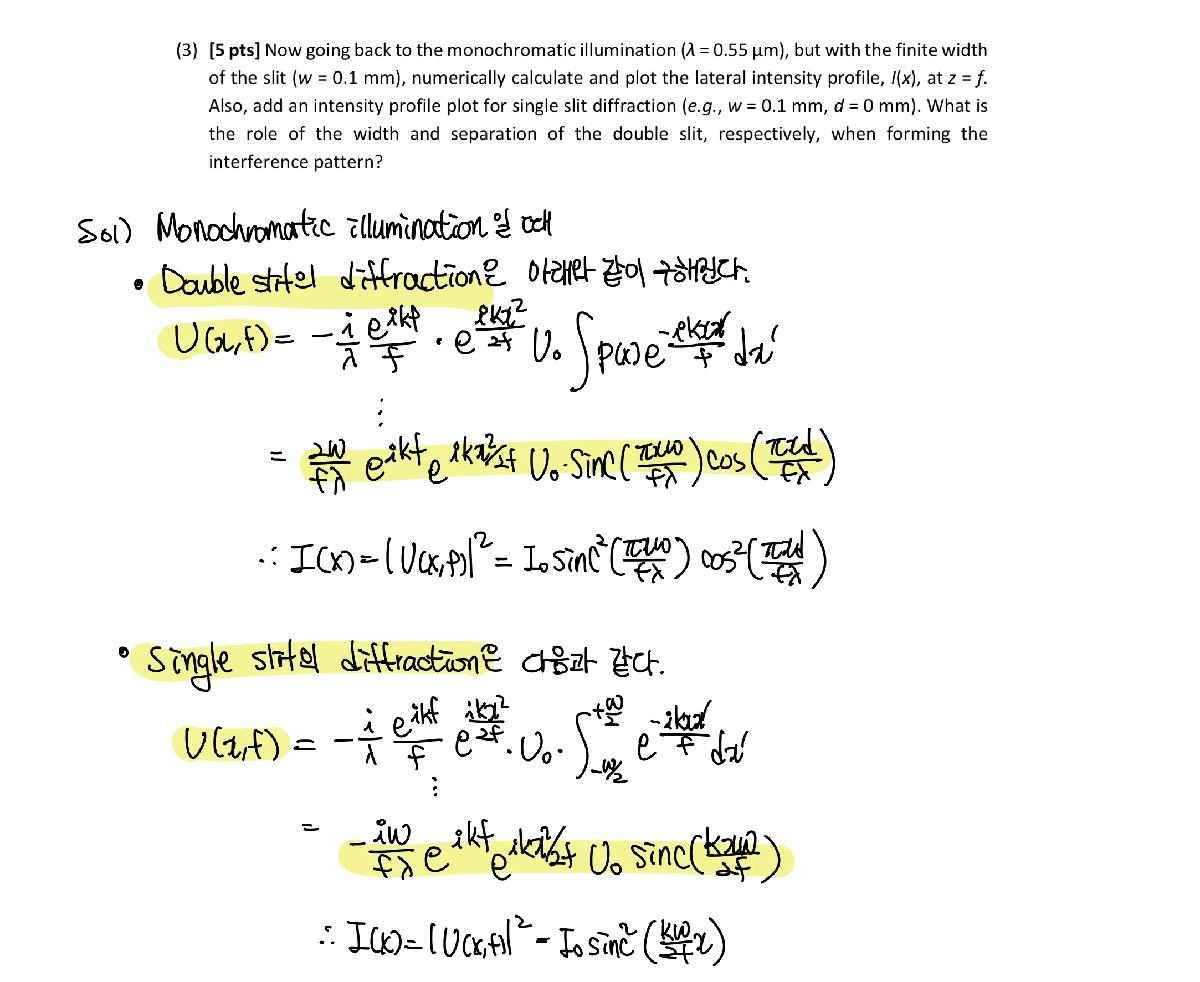

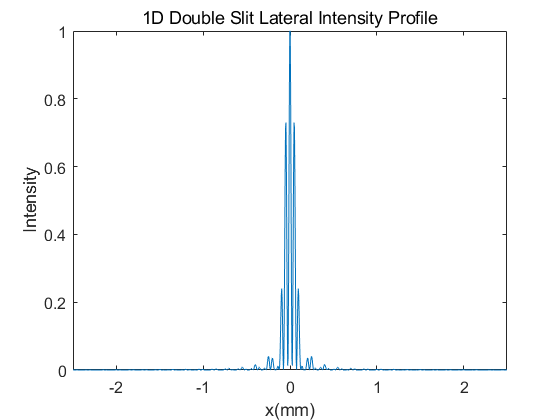

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate and plot the double slit lateral intensity profile at z=f and w=0.1mm.
% Plot the single slit diffraction at w=0.1mm, d=0mm.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

lambda = 0.0005; % mm, wavelength
k = 2*pi/lambda;

Nx = 1024;
x = linspace(-2.5,2.5,Nx);

f= 100; % mm, z=f
d = 1; % mm, distance between two slits 
w = 0.1; % mm, silt width

% 1D double slit Lateral Intensity profile
func_ds = (2.*w./f./lambda)*exp(1i.*k.*f).*exp((1i.*k.*(x.^2))./(2.*f)).*1.*...
    sinc((pi.*x.*w)./(f.*lambda)).*cos((pi.*x.*d)./(f.*lambda)); %% assume U0 as 1
I = abs(func_ds).^2;
I_nor = I/max(I); % Normalized

figure; plot(x, I_nor);
set(gca, 'Fontsize', 12);
xlim([-2.5, 2.5]);
title('1D Double Slit Lateral Intensity Profile'); xlabel('x(mm)');ylabel('Intensity');

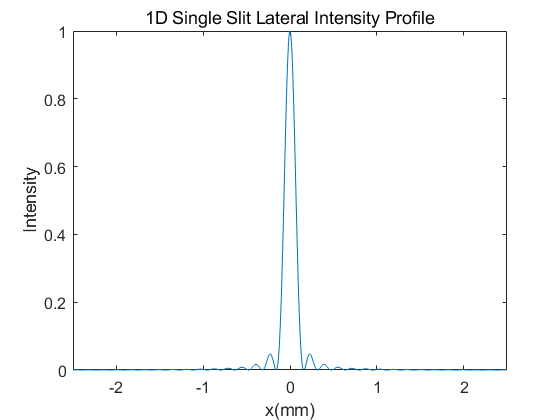

% 1D single slit diffraction at w=0.1mm, d=0mm.

func_ss = ((-1i.*w)./(f.*lambda)).*exp(1i.*k.*f).*exp(1i.*k.*(x.^2)./(2.*f)).*1.*sinc((k.*w.*x)./(2.*f)); %% assume U0 as 1
I_ss = abs(func_ss).^2;
I_ssn = I_ss/max(I_ss);

figure; plot(x, I_ssn);
set(gca, 'Fontsize', 12);
xlim([-2.5, 2.5]);
title('1D Single Slit Lateral Intensity Profile'); xlabel('x(mm)');ylabel('Intensity');

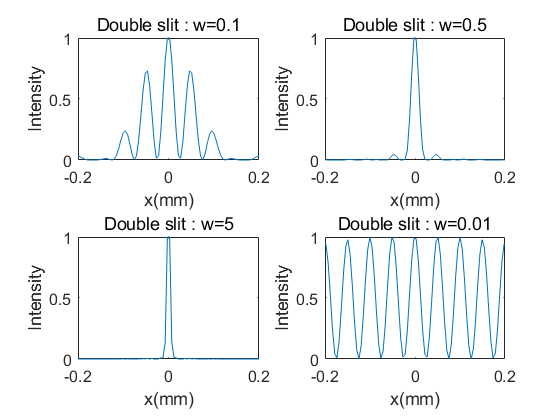

%% 1D Lateral Intensity Profile with different width of the slit

save = zeros(4,Nx);
save_singleslit = zeros(4,Nx);
w_list = [0.1 0.5 5 0.01];

% Double slit diffration with different ws.
for w_cnt = 1:length(w_list)
    func_ds = (2.*w_list(w_cnt)./f./lambda)*exp(1i.*k.*f).*exp((1i.*k.*(x.^2))./(2.*f)).*1.*...
        sinc((pi.*x.*w_list(w_cnt))./(f.*lambda)).*cos((pi.*x.*d)./(f.*lambda)); %% assume U0 as 1
    I_ws = abs(func_ds).^2;
    I_ws_nor = I_ws/max(I_ws); % Normalized
    save(w_cnt,:) = I_ws_nor;
end

figure; subplot(2,2,1);
plot(x, save(1,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Double slit : w=0.1'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,2);
plot(x, save(2,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Double slit : w=0.5'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,3);
plot(x, save(3,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Double slit : w=5'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,4);
plot(x, save(4,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Double slit : w=0.01'); xlabel('x(mm)');ylabel('Intensity');

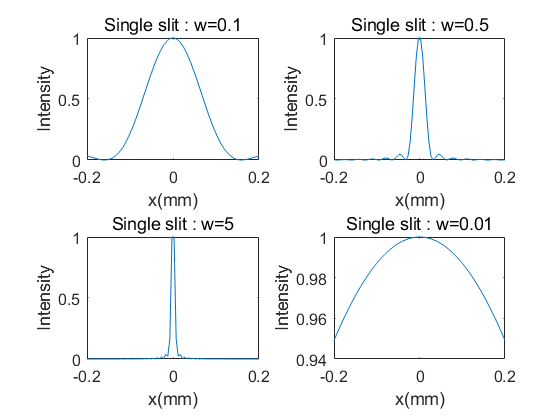


% Single slit diffration with different ws.

for w_cnt = 1:length(w_list)
    func_ss = ((-1i.*w_list(w_cnt))./(f.*lambda)).*exp(1i.*k.*f).*exp(1i.*k.*(x.^2)./(2.*f)).*1.*sinc((k.*w_list(w_cnt).*x)./(2.*f)); %% assume U0 as 1
    I_ss_w = abs(func_ss).^2;
    I_ssn_w_nor = I_ss_w/max(I_ss_w);
    save_singleslit(w_cnt,:) = I_ssn_w_nor;
end

figure; subplot(2,2,1);
plot(x, save_singleslit(1,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Single slit : w=0.1'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,2);
plot(x, save_singleslit(2,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Single slit : w=0.5'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,3);
plot(x, save_singleslit(3,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Single slit : w=5'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,4);
plot(x, save_singleslit(4,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Single slit : w=0.01'); xlabel('x(mm)');ylabel('Intensity');

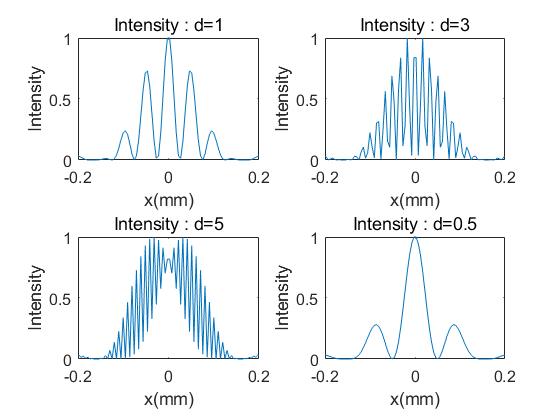

%% 1D Double Slit Lateral Intensity Profile with different separations of the double slit

saves = zeros(4,Nx);
d_list = [1 3 5 0.5];

for d_cnt = 1: length(d_list)
    % 1D double slit Lateral Intensity profile
    func_ds = (2.*w./f./lambda)*exp(1i.*k.*f).*exp((1i.*k.*(x.^2))./(2.*f)).*1.*...
        sinc((pi.*x.*w)./(f.*lambda)).*cos((pi.*x.*d_list(d_cnt))./(f.*lambda)); %% assume U0 as 1
    I_ds = abs(func_ds).^2;
    I_ds_nor = I_ds/max(I_ds); % Normalized
    saves(d_cnt,:) = I_ds_nor;
end

figure; subplot(2,2,1);
plot(x, saves(1,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Intensity : d=1'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,2);
plot(x, saves(2,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Intensity : d=3'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,3);
plot(x, saves(3,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Intensity : d=5'); xlabel('x(mm)');ylabel('Intensity');

subplot(2,2,4);
plot(x, saves(4,:));
set(gca, 'Fontsize', 12);
xlim([-0.2, 0.2]);
title('Intensity : d=0.5'); xlabel('x(mm)');ylabel('Intensity');

Lambda가 0.55$\mu m$ 인 Monochromatic illumination이 double slit을 통과했을 때와 single slit을 통과했을 때 z=f에서의 lateral intensity profile을 위와 같이 계산하였다.

또한 width와 separation을 바꿔가면서 intensity profile 그래프가 어떻게 변화하는지 계산하였다.

- **The role of the width and separation of the double slit  :**

                *** Width :** Width는 Intensity profile intensity profile에서 간섭 패턴의 전체적인 graph 개형을 결정한다. 

                w 값을 다양하게 줬을 때의 intensity profile을 보면, w가 커지면 커질수록 intensity profile의 폭이 줄어들고 sinc 함수의 attenuation이 커지는 것을 볼 수 있다.

                마찬가지로 single slit에서도 width가 크면 클수록 intensity profile의 폭이 줄어들고 sinc 함수의 attenuation이 커지는 것을 볼 수 있다.

                이는 수식을 통해 보면 이해가 빠른데, sinc 함수는 다음과 같이 sin함수로 나타낼 수 있다.


$$\textrm{sinc}\left(t\right)=\frac{\sin \left(\pi t\right)}{\pi t}$$


                따라서 width 값(w)이 커질수록 주기는 작아지게 되고 고로 intensity pattern의 폭이 줄어들게 되며 분모의 attenuation coefficient가 커져 attenuation이 더 많이 되는 것이다.

               *** Separation : **Separation of the double slit은 intensity profile에서 간섭 패턴의 fluctuation을 결정한다.

                Double slit diffraction에서 d값이 커지면 커질수록 intensity profile이 더 fluctuation하는 것을 볼 수 있다. 

                수식을 통해 보면 이해가 빠른데, Double slit diffraction의 intensity equation을 보면 single slit일 때보다 $\cos^2$ term이 곱해져있다.

                이 때, Assignment 2-(1)에서도 구했듯이 $\cos^2$ 함수는 주기함수이며 $\cos^2$ 함수의 주기는 $\frac{\lambda f}{d}$이다. 

                따라서 d가 증가하면 주기가 작아지므로 이것이 sinc 함수에 곱해져 sinc 함수로 만들어지는 기본적인 intensity profile에서 더 fluctuate 하느냐, 아니면 덜 하느냐를 결정하게 된다.